clc
clear all
close all

# Cruise Controller

### Japnit Sethi

**Benefits of Feedback:**

- Stability

- uncertainty in the plant

- disturbance

**Situation:** cruise control of a car on a terrain with some disturbances that the open-loop model is not aware of, including some model uncertainties like messed up tire angle, winds etc.

**Input**: stepping on gas/break pedal (u)

**Output**: speed (y)

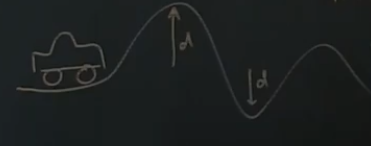

# Open loop model 

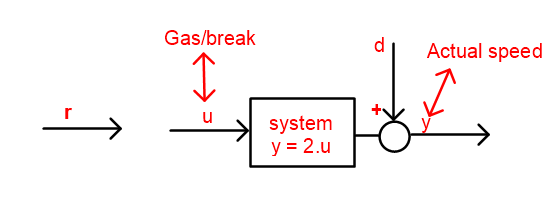

Let's just assume in our crude model for the system it is y = 2.u i.e if we put a foot down the gas pedal for every 2 units of force on the pedal, it produces a unit of speed to the car.

Assuming I have some r**eference speed 'r'** I want to track, then for y to be equal to r, i would have to push pedal such that:

2.u = r $\Leftrightarrow$ $u_{\mathrm{OL}}$ = $\frac{r}{2}$

Note: Now see in the open-loop model there is no accountability for the disturbance and the uncertainty. 

Now going for the True Model:

y = u + d $\Leftrightarrow$ $y_{\mathrm{OL}}$ = $\frac{r}{2}$ + d , and thus we can see all of our disturbances pass right though our open loop system and has no way of correcting it

Equation of Motion:

y = 2.u

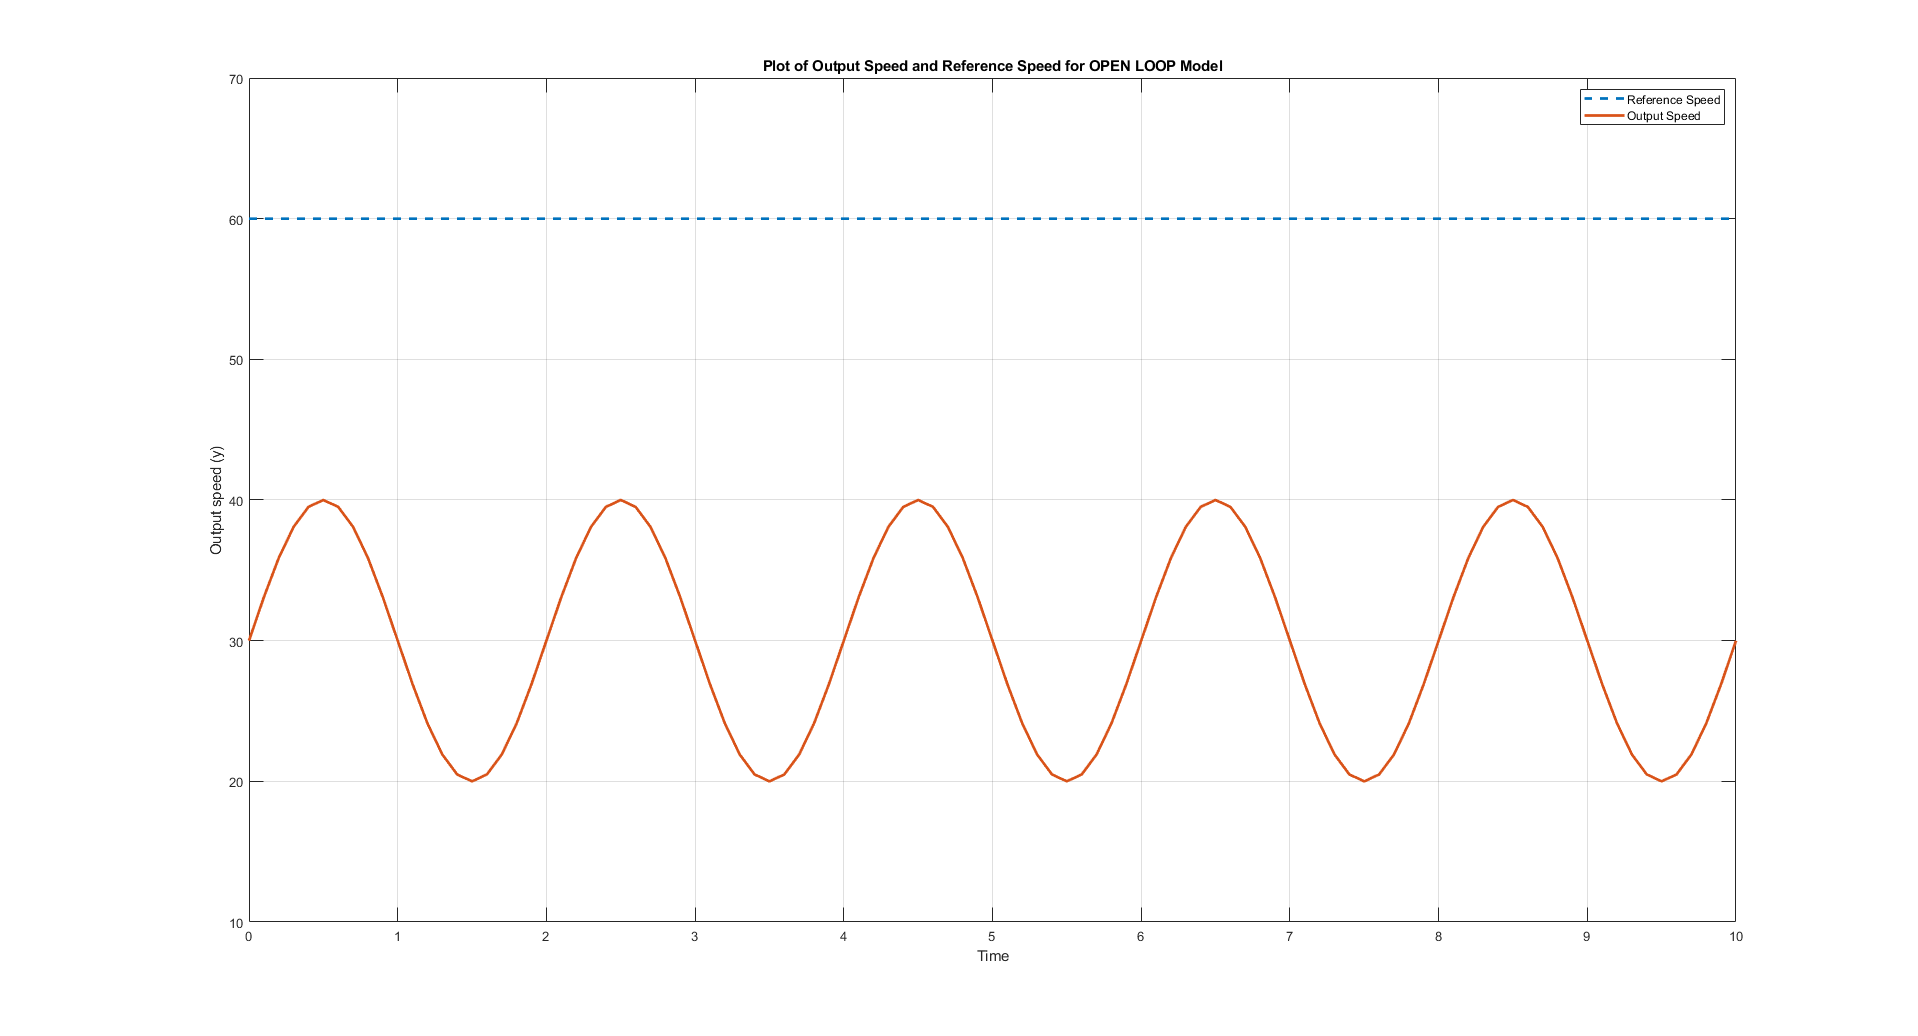

t = 0:0.1:10;                           % time 0 to 10 units

wr = 60 + 0*t;                          % reference speed
d = 10*sin(pi*t);                       % disturbance

% Below the open loop model is purely based on the model of the car, so it
% has a model of P = 2, that is if we hit the pedal then car speeds up by
% twice the units
aModel = 2;                             % y = aModel*u

% But in reality since we have some uncertainty, and in reality our pedal
% is just have as responsive
aTrue = 1;                              % y = aTrue*u

uOL = wr/aModel;                        % Open-loop u based on model, Foreg. uOl = r/2, here 2 is Model of the car
yOL = aTrue*uOL + d;                    % Open-loop response, the correcting for response with true model i.e 1; 1*(r/2) + d

figure()
plot(t, wr, 'linewidth', 2, 'linestyle', '--');
hold on
grid on
plot(t, yOL, 'linewidth', 2);
% Setting figure background color to grey
% set(gca,'Color', [0.75 0.75 0.75]);

title('Plot of Output Speed and Reference Speed for OPEN LOOP Model');
xlabel('Time')
ylabel('Output speed (y)')
legend('Reference Speed', 'Output Speed');
xlim([0 t(end)]);
ylim([10 70]);
hold off

% In order to maximize the figure window in Windows
set(gcf, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, 1, 0.96]);

# Closed Loop (Proportional Control)

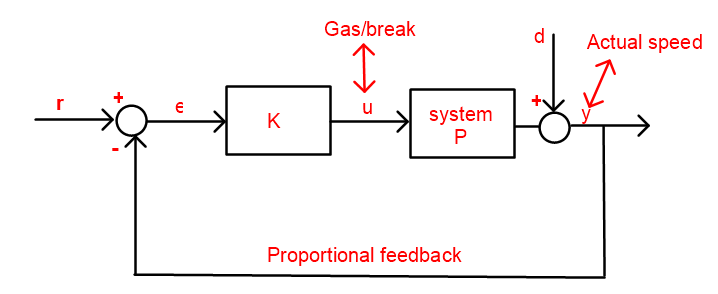

So in order to account for our disturbances we close the loop, and subtract the output y from the reference speed r which gives us our error $\varepsilon$, and thus now we choose the controller with gain k such that the error is diminished to 0.

Assuming that for the True car model it has a transfer function P

Therefore:

$u_{\mathrm{CL}}$ = K.$\varepsilon$ = K.(r - y)

$y_{\mathrm{CL}}$ = P.$u_{\mathrm{CL}}$ + d = P.K.r - P.K.$y_{\mathrm{CL}}$ + d  $\Leftrightarrow \;$ (1 + P.K).$y_{\mathrm{CL}}$ = P.k.r + d   $\Leftrightarrow \;$  $y_{\mathrm{CL}}$ = $\frac{P\ldotp K}{1+\mathrm{PK}}r$  + $\frac{1}{1+\mathrm{PK}}\ldotp d$

Note: in the above for Y closed loop we want the term $\frac{P\ldotp K}{1+\mathrm{PK}}$ to be equal to 1 so our reference tracking be good, and we want $\frac{1}{1+\mathrm{PK}}$ this to be 0 so we completely diminish the disturbance.

And for the above to happen we want to make our proportional gain K be huge

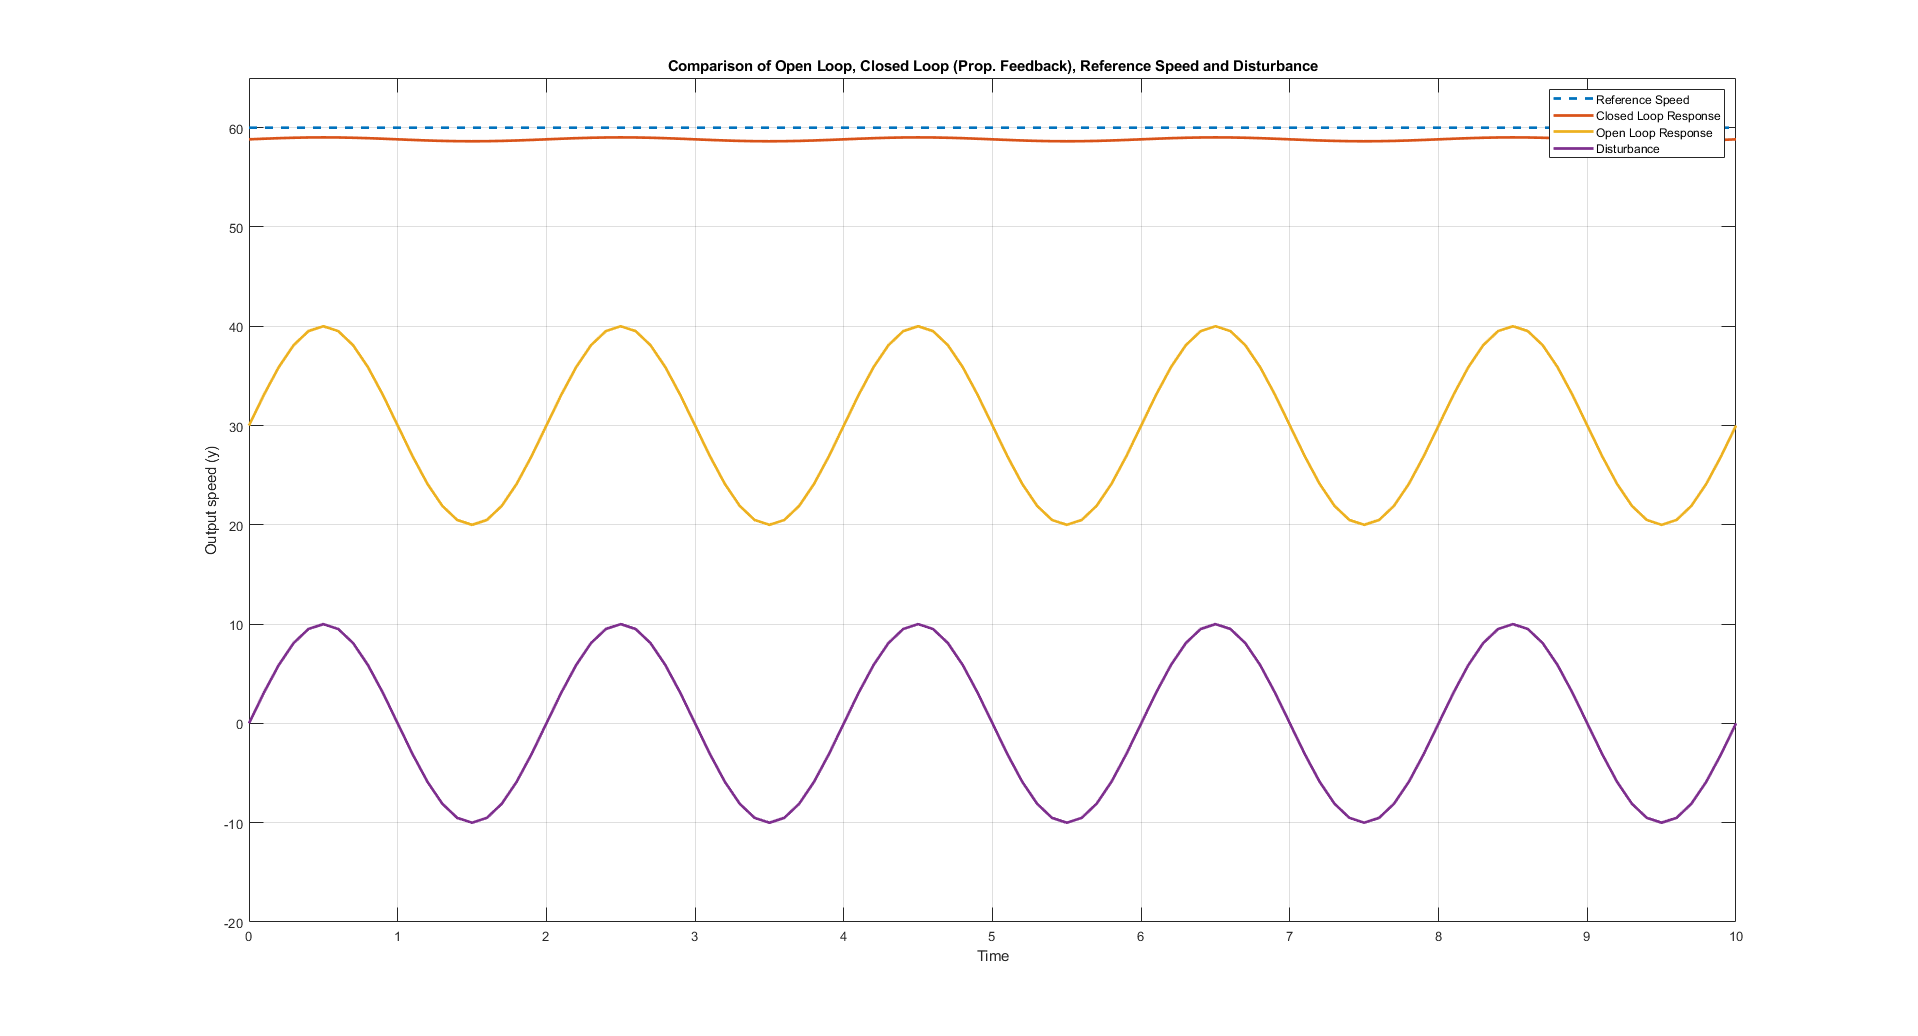

K = 50;                                                 % Proportional Feedback gain, u = K(wr - y)
yCL = aTrue*K/(1 + aTrue*K)*wr + d/(1 + aTrue*K);       % Closed Loop response with Proportional feedback

figure()
plot(t, wr, 'linewidth', 2, 'linestyle', '--');
hold on
grid on
plot(t, yCL, 'linewidth', 2);
plot(t, yOL, 'linewidth', 2);
plot(t, d, 'linewidth', 2);
% Setting figure background color to grey
% set(gca,'Color', [0.75 0.75 0.75]);

title('Comparison of Open Loop, Closed Loop (Prop. Feedback), Reference Speed and Disturbance');
xlabel('Time')
ylabel('Output speed (y)')
legend('Reference Speed', 'Closed Loop Response', 'Open Loop Response', 'Disturbance');
xlim([0 t(end)]);
ylim([-20 65]);
hold off

% In order to maximize the figure window in Windows
set(gcf, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, 1, 0.96]);

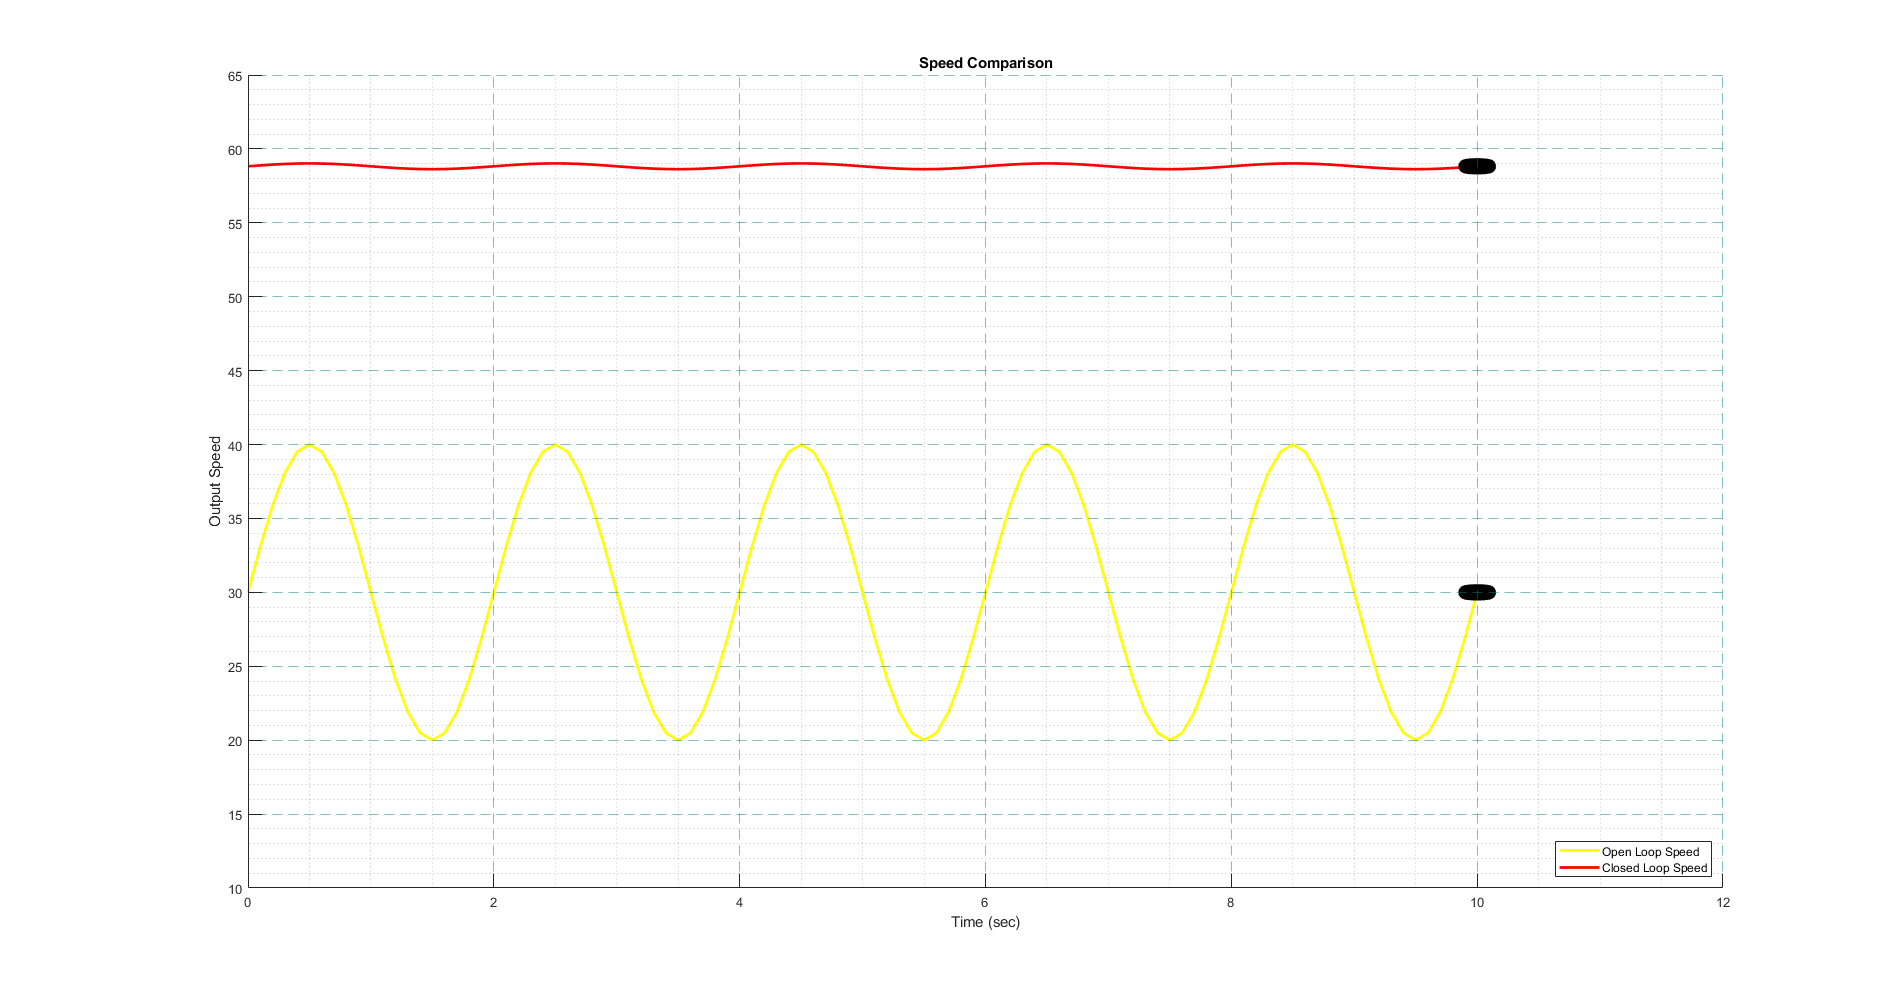

% Animation

myVideo = VideoWriter('Speed Comparison'); % open video file
myVideo.FrameRate = 10;  
open(myVideo)
pc = [-.1 -.1 .2 .2] ; % position of circle

figure 
grid on
grid minor

ax = gca;
ax.GridColor = [0 .5 .5];
ax.GridLineStyle = '--';
ax.GridAlpha = 0.5;
ax.Layer = 'top';

h1 = animatedline('Color','y','LineWidth', 2); 
h2 = animatedline('Color','r','LineWidth', 2);
hc1 = rectangle('Position', [t(1) yOL(1) 0 0]+pc,'Curvature',[1 1], 'FaceColor','y', 'LineWidth', 10) ; % draw circle
hc2 = rectangle('Position', [t(1) yCL(1) 0 0]+pc,'Curvature',1, 'FaceColor','r', 'LineWidth', 10) ; % draw circle

for k = 1:length(t) 
  addpoints(h1, t(k),yOL(k)); 
  addpoints(h2, t(k),yCL(k));
  set(hc1,'Position', [t(k) yOL(k) 0 0] + pc) ; % adjust position of circle
  set(hc2,'Position', [t(k) yCL(k) 0 0] + pc) ; % adjust position of circle
 
  pause(0.01)  % Pause and grab frame
  frame = getframe(gcf); % get frame
  writeVideo(myVideo, frame);
  title('Speed Comparison');
  xlabel('Time (sec)');
  ylabel('Output Speed');
  h = legend('Open Loop Speed', 'Closed Loop Speed');
  set(h, 'Location','southeast');
  ylim([10 65]);
%   xlim([0 1.4]);
end
% In order to maximize the figure window in Windows
set(gcf, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, 1, 0.96]);


close(myVideo)
drawnow

# Closed Loop (Proportional-Integral Control)

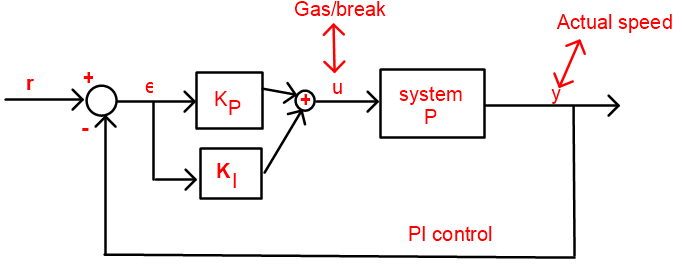

Now, we know even with Proportional feedback there was some steady state error which we ca eliminate with Integral control

In the absence of disturbances, there is always going to some difference between reference signal and our y with just Proportional controller: $y_{\mathrm{CL}}$ = $\frac{P\ldotp K}{1+\mathrm{PK}}r$  

 The **integral control** helps in reducing the **steady state error to 0**

Originial Model was pretty crude:

Where, y = 2.u    i.e.    P = 2  was our transfer function

But now, we'll add a **realistic dynamic model to the car**


$$\dot{x\;} =-x+u$$


y = x

Therefore, the Transfer function now is:

$\frac{y\left(s\right)}{u\left(s\right)}$ = P(s) = $\frac{1}{s+1}$

$u_{\mathrm{CL}}$ = $K_P$.$\left(r-y\right)$ + $K_I$.$\int \left(r-y\right)\ldotp \mathrm{dt}$

Now, let $\dot{z}$ = r - x,   Therefore: $u_{\mathrm{CL}}$ = $K_P$.$\left(r-y\right)$ + $K_I$.z

Now, substituting value of u into $\dot{x\;}$

We get,

$\dot{x\;} =-x+$ $K_P$.$\left(r-y\right)$ + $K_I$.z

$\dot{z}$ = r - x

In State Space form,


$$\left\lbrack \begin{array}{c}
\dot{x} \\
\dot{z} 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
-1-K_P  & K_I \\
-1 & 0
\end{array}\right\rbrack \ldotp \left\lbrack \begin{array}{c}
x\\
z
\end{array}\right\rbrack +\left\lbrack \begin{array}{c}
-K_P \\
1
\end{array}\right\rbrack \ldotp r$$


y = $\left\lbrack \begin{array}{cc}
1 & 0
\end{array}\right\rbrack$.$\left\lbrack \begin{array}{c}
x\\
z
\end{array}\right\rbrack$

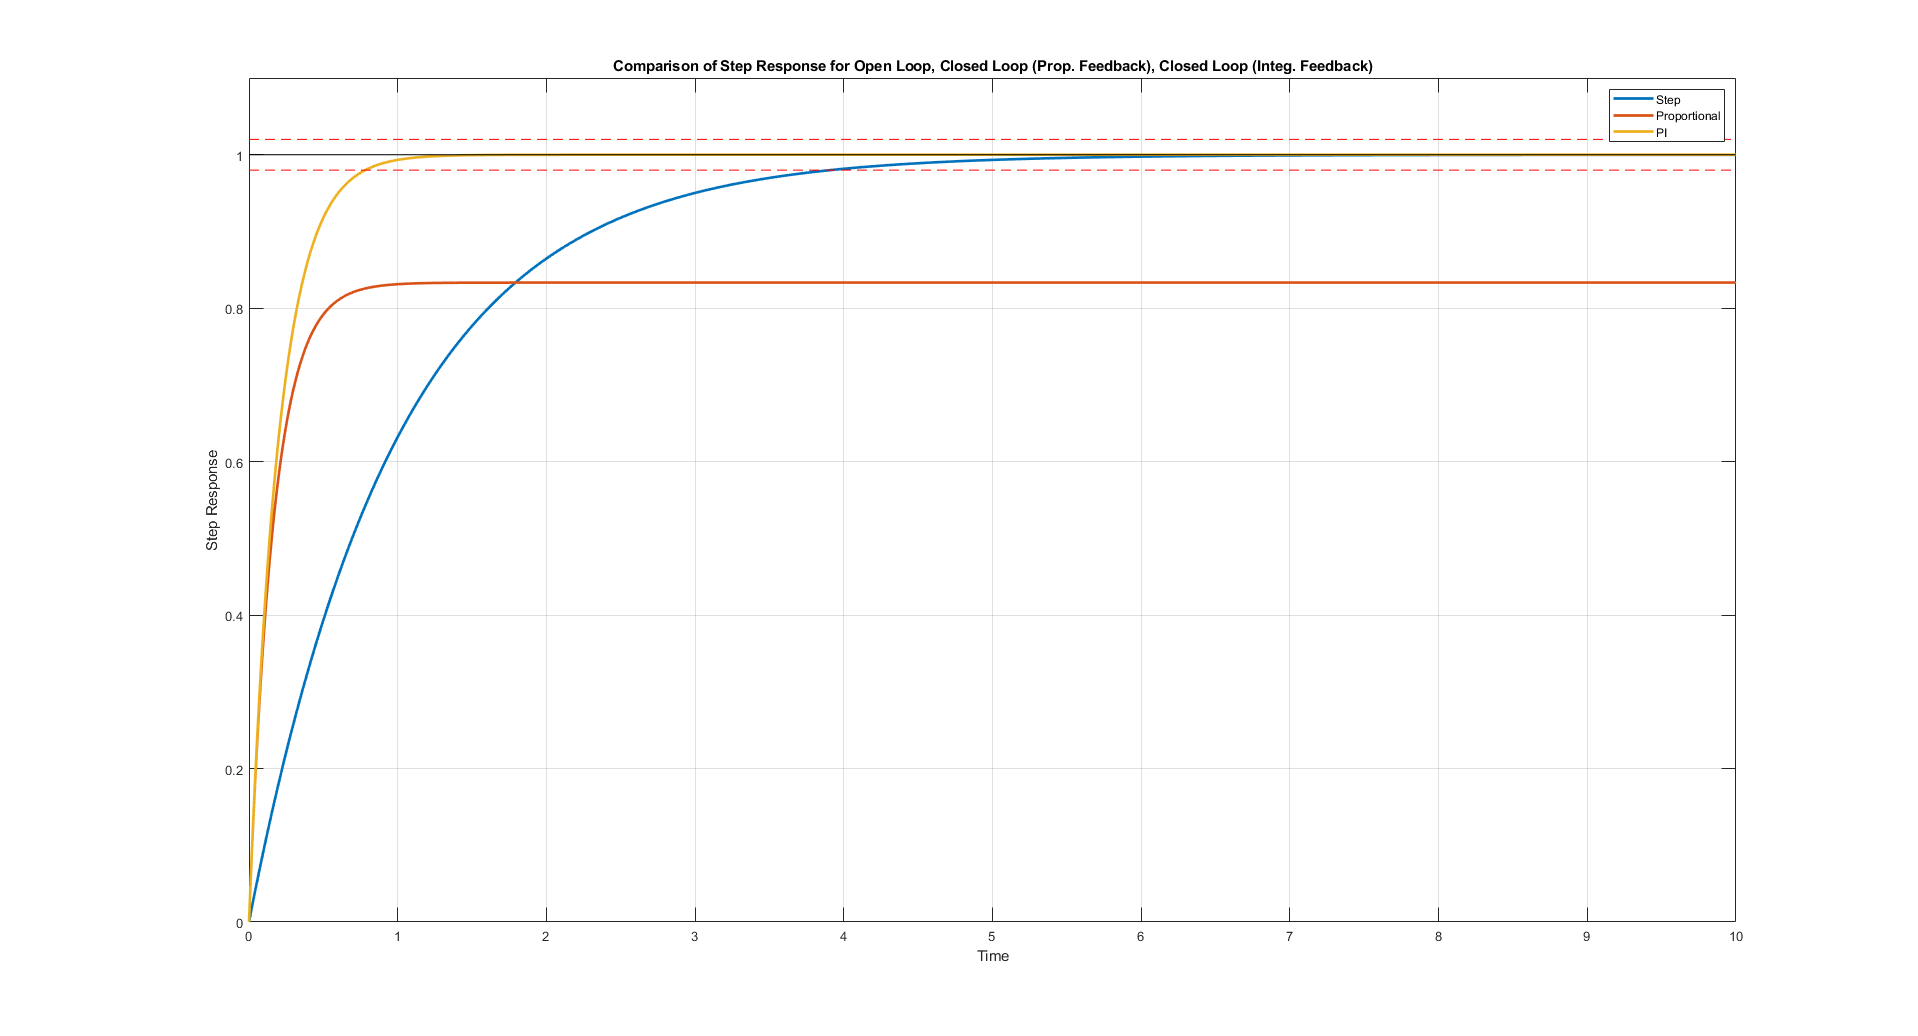

% Open-loop car model without any feedback
sysCar = ss(-1, 1, 1, 0);

% Model if we just have the Proportional gain K
K = 5;
sysP = ss(-1-K, K, 1, 0);

t = 0:0.01:10;
[yCar, tCar, xCar] = step(sysCar, t);
[yP, tP, xP] = step(sysP, t);

figure()
plot(tCar, yCar, 'linewidth', 2);
hold on
grid on
plot(tP, yP, 'linewidth', 2);

% Closed loo[ state space model with both integral and proportional gain,
% but we are just assuming value of both gains to be same
A = [-1-K, K; -1, 0];
B = [K; 1];
C = [1, 0];
D = 0;

sysPI = ss(A, B, C, D);

[yPI, tPI, xPI] = step(sysPI, t);
plot(tPI, yPI, 'linewidth', 2);
hRef1=refline(0,1);
set(hRef1,'color','k'); % Max horizontal
hRef2=refline(0,1.02);
set(hRef2,'color','r','linestyle','--'); % Max horizontal
hRef3=refline(0,0.98);
set(hRef3,'color','r','linestyle','--'); % Min horizontal
title('Comparison of Step Response for Open Loop, Closed Loop (Prop. Feedback), Closed Loop (Integ. Feedback)');
xlabel('Time')
ylabel('Step Response')
legend('Step', 'Proportional', 'PI');
xlim([0 t(end)]);
ylim([0 1.1]);
hold off

% In order to maximize the figure window in Windows
set(gcf, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, 1, 0.96]);

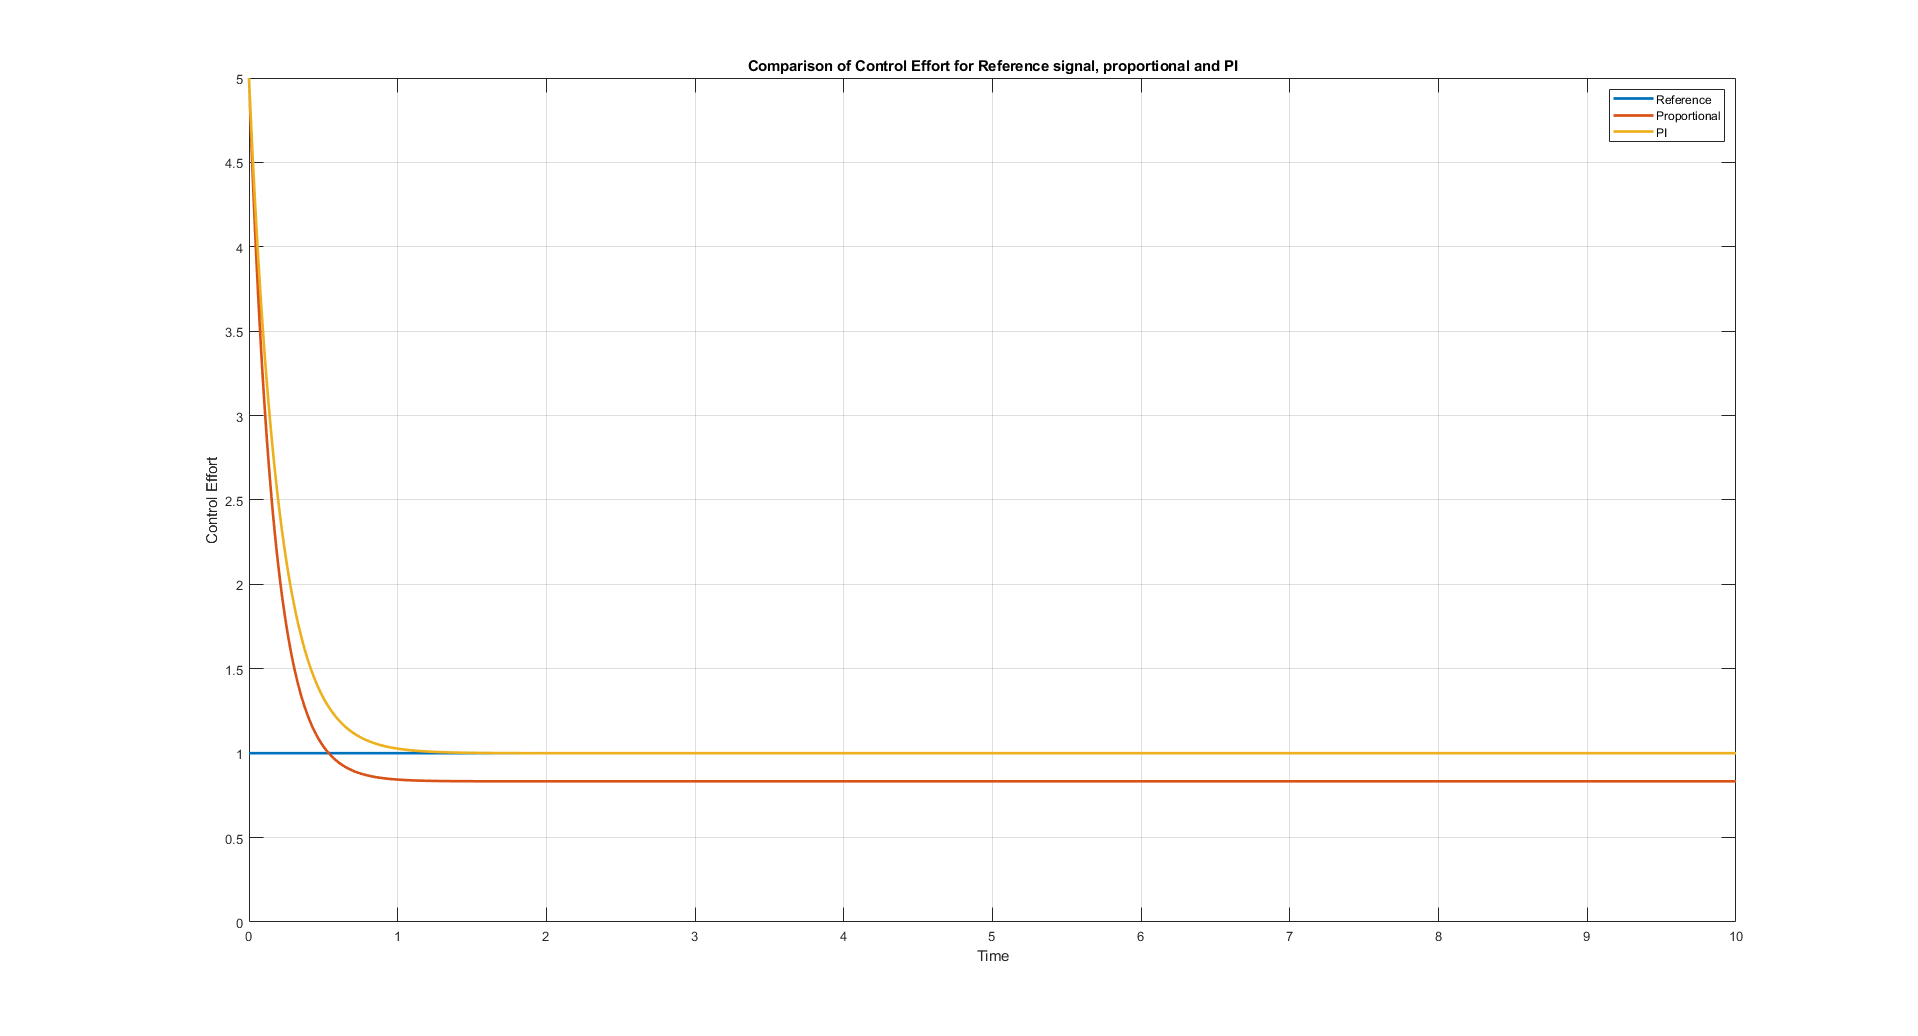

% Plotting the Control effort for each response now
% That is the effort required (how much and at what instance) during
% functioning of each controller

figure()
% Set Point that is just u, u.e. we are just going to hold the gas at 1
% because that is the final amount gas for us
plot(t, 0*t + 1, 'linewidth', 2);
hold on
grid on
% Proportional
plot(tP, K*(1-xP), 'linewidth', 2);
xPIminusRef = xPI;
xPIminusRef(:,1) = 1 - xPI(:,1);
plot(tPI, (xPIminusRef)*[K; K], 'linewidth', 2);
title('Comparison of Control Effort for Reference signal, proportional and PI');
xlabel('Time')
ylabel('Control Effort')
legend('Reference', 'Proportional', 'PI');
xlim([0 t(end)]);
ylim([0 5]);
hold off

% In order to maximize the figure window in Windows
set(gcf, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, 1, 0.96]);

% So we could see in above that In proportional we jammed on the gas way
% too much whereas the PI feathers down the control effort to the set point
% smoothly

# Loop Shaping

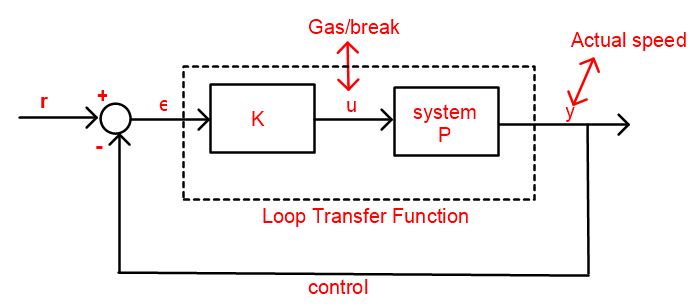

We would like our "loop transfer function" to look like an integrator:

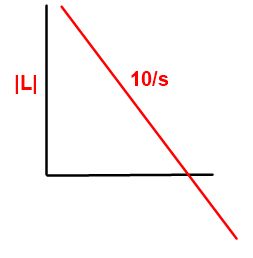

**Reason for an integrator shape of loop transfer function:** For good noise attenuation, disturbance rejection and reference tracking.

 Normally for an integrator in laplace domain the function is 1/s but we would like to be able to choose the **bandwidth** $\omega$ = 10 that is it would have an effective reference tracking ability for bandwidths below $\omega$(which is 10 in our case), and is going to have noise attenuation for frequancies above $\omega$

So we know our Trasfer function of the system is P(s) = $\frac{1}{s+1}$

and thus let Loop transfer function be L(s) : 

where,

L(s) = P(s).K = $\frac{10}{s}$  $\Rightarrow \;$$\frac{1}{s+1}\ldotp K\;$ = $\frac{10}{s}$  $\Rightarrow \;$$K\;$ = $\frac{10\left(s+1\right)}{s}$

**Caution:**

In general, the above is a bad idea where we inverted the plant transfer function (1/(s+1)) to get the value of K, because imagine if the plant had right half plane poles such that if we invert it, we would have a right hand plane zero and wouldresult in an unstable system and unobservable where the system is unstable.

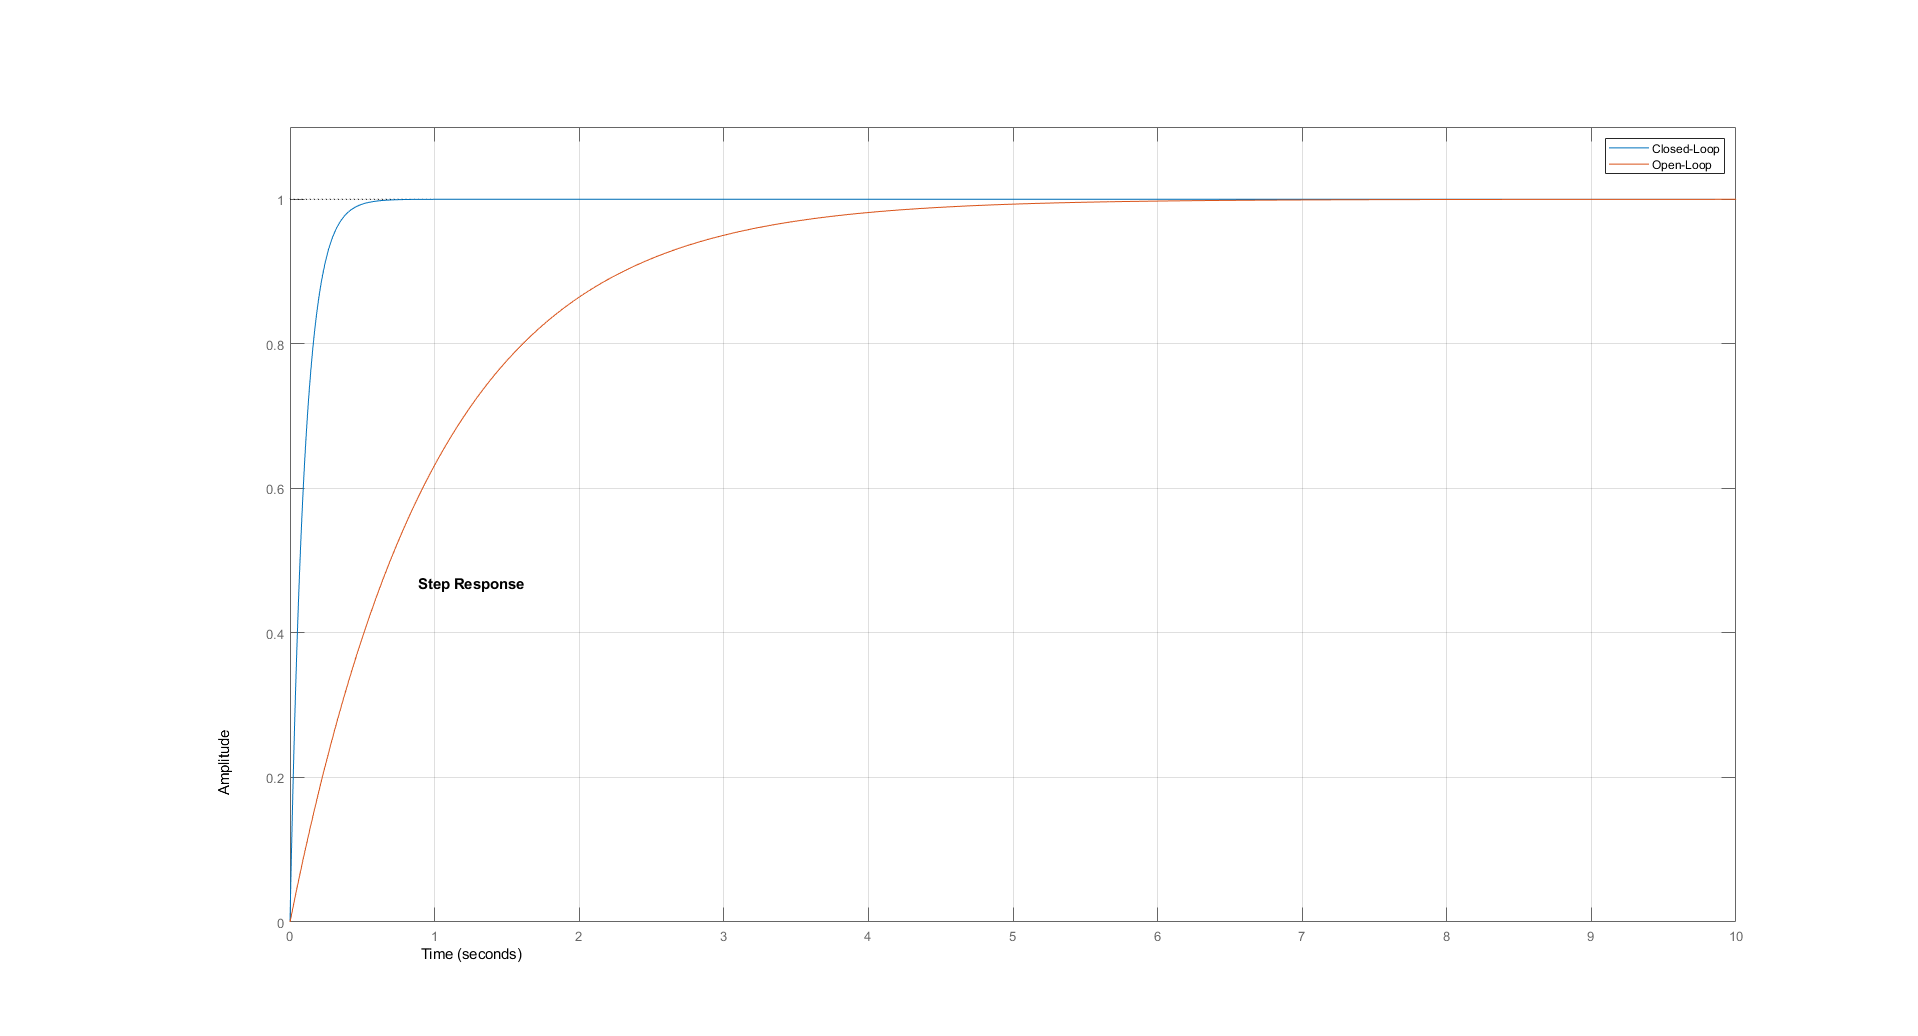

% Usin the same state space form of car model and converting it to transfer function form

% Option one: full conversion
% [num, den] = ss2tf(sysCar.a, sysCar.B, sysCar.C, sysCar.D);
% tfCar = tf(num, den);

% Option 2: Just write down the plant transfer function
s = tf('s');
tfCar = 1/(s+1);

% Big gain (10) times the integrator (1/s) for better bandwidth performance
DesiredLoop = 10/s;  % Our desired loop shape as discussed above i.e. the Integrator

% Controller K
K = DesiredLoop/tfCar;

% Creating a series of K followed by Plant
sysLoop = series(K, sysCar);
% Feedback around the Loop
sysCL = feedback(sysLoop, 1, -1);

figure()
step(sysCL);
hold on
grid on
grid minor
% Open loop system step response
step(sysCar);
title('Step Response');
xlabel('Time')
ylabel('Amplitude')
legend('Closed-Loop', 'Open-Loop');
xlim([0 t(end)]);
ylim([0 1.1]);
hold off

% In order to maximize the figure window in Windows
set(gcf, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, 1, 0.96]);

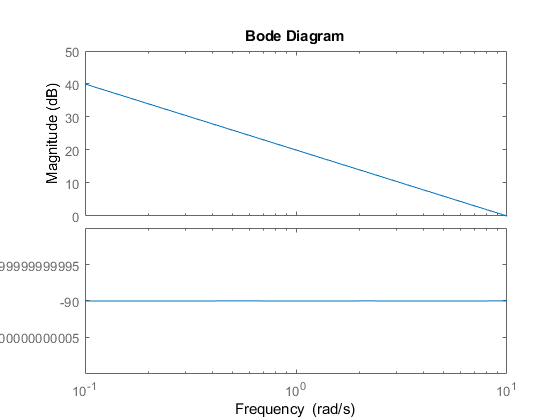

% Bode Plot
figure()
bode(sysLoop); 
hold on

bode(DesiredLoop); 